# Compund pendulum

Physics lab 1 exam

manca da calcolare rappresentare g con la propagazione degli errori.

% cleaning
clc
clear

% importing data
df1=readtable("..\data\exp-data-1.csv");
df2=readtable("..\data\exp-data-2.csv");
tools=readtable("..\data\tools.csv");

toDelete = df2.configuration == 14;
df2(toDelete,:) = [];

% count configurations
uc=unique(df2.configuration); % unique configuration
nc=length(uc);                % number of configs

## Prima esplorazione e distribuzione delle misure indirette

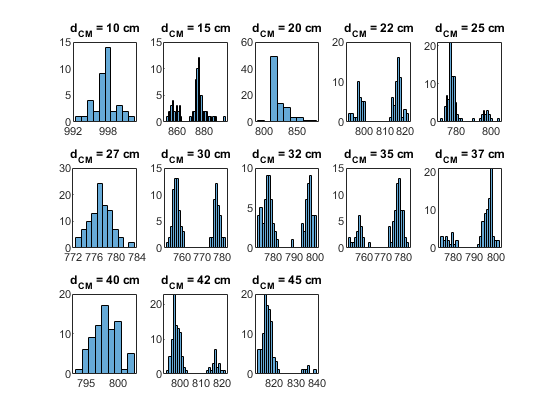

hst=figure;
for i=1:nc
    subplot(3,5,i)
    histogram(table2array(df2(df2.configuration==uc(i),"time_ms")))     
    % title(strcat("Configuration",string(uc(i)), "distanza dal CM = ", string(table2array(df1(df1.configuration==uc(i),"distance_cm"))-50), " cm"))
    title(strcat("d_{CM} = ", string(table2array(df1(df1.configuration==uc(i),"distance_cm"))-50), " cm"))
end
% exporting plot
saveas(hst,'..\img\histogram.png');

## Deviazione standard e scarti normalizzati

Per stimarla, calcolo la deviazione standard sui tempi per ogni configurazione

% calcolo la deviazione standard dei tempi misurati
for i=1:nc
    % calcolo la media
    tm(i)=round(mean(table2array(df2(df2.configuration==uc(i),"time_ms"))),0);

    % calcolo la deviazione
    deviation(i)=round(std(table2array(df2(df2.configuration==uc(i),"time_ms"))),0);
end

% creo tabella
dev = table(uc, tm', deviation','VariableNames',{'configuration','mean_ms','deviation'});

% calcolo rapporto tra deviazione/media)
dev.ratio = round((dev.deviation./dev.mean_ms).*100,2);
% writetable(dev,'..\data\temp.csv','Delimiter',',','Encoding','UTF-8')

## Rigetto di dati

% calcolo distanza dalla media in valore assoluto per ogni valore (scarti
% normalizzati t)

% join con dev per ottenere tempi medi (mean_ms)
df2 = join(df2,dev,"Keys","configuration");
df2 = df2(:,["configuration","event","time_ms","mean_ms","deviation"]);
df2.difference = abs(df2.time_ms - df2.mean_ms);

% calcola di quante deviazioni standard il valore è fuori
df2.out = round(df2.difference ./ df2.deviation,1);

% elimino i valori che sono fuori di più di 3.5 sigma
df2 = df2(df2.out <= 4,:)

df2 = 1118×7 table
    configuration    event    time_ms    mean_ms    deviation    difference    out
    _____________    _____    _______    _______    _________    __________    ___

          1            1       1002        998          2            4           2
          1            2        995        998          2            3         1.5
          1            3        998        998          2            0           0
          1            4       1000        998          2            2           1
          1            5        996        998          2            2           1
          1            6        998        998          2            0           0
          1            7        997        998          2            1        

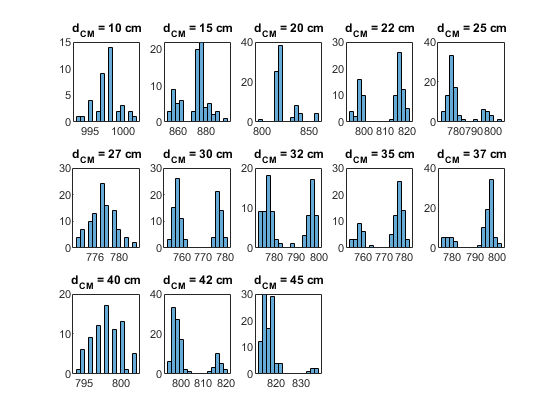

% aggiorno variabili
uc=unique(df2.configuration); % unique configuration
nc=length(uc);                % number of configs

% histogram
hst=figure;
for i=1:nc
    subplot(3,5,i)
    histogram(table2array(df2(df2.configuration==uc(i),"time_ms")),15)     
    % title(strcat("Configuration",string(uc(i)), "distanza dal CM = ", string(table2array(df1(df1.configuration==uc(i),"distance_cm"))-50), " cm"))
    title(strcat("d_{CM} = ", string(table2array(df1(df1.configuration==uc(i),"distance_cm"))-50), " cm"))
end

Alla luce dell'applicazione del criterio di Chauvenet, ricalcolo media e deviazione

% delete old mean and deviation
df2 = df2(:,["configuration", "event", "time_ms"]);

% calcolo la deviazione standard dei tempi misurati
for i=1:nc
    % calcolo la media
    tm(i)=round(mean(table2array(df2(df2.configuration==uc(i),"time_ms"))),0);
    % calcolo la deviazione
    deviation(i)=round(std(table2array(df2(df2.configuration==uc(i),"time_ms"))),0);
end

% creo tabella
% dev = table(uc, tm', deviation','VariableNames',{'configuration','mean_ms','deviation'});

% calcolo rapporto tra deviazione/media)
% dev.ratio = round((dev.deviation./dev.mean_ms).*100,2)

% aggiorno variabili
uc=unique(df2.configuration); % unique configuration
nc=length(uc);                % number of configs
l=1;                          % pendulum length
g=9.81;                       % gravitational acceleration
dg=0.01;                      % error gravitational acceleration
dt=tools.uncertainty(1);      % error t
dr=tools.uncertainty(2);      % errror distance

% overwrite distance error
dr = 0.002; % meters

% creating empty array
tm=zeros(nc,1);     % tempi medi
d=zeros(nc,1);      % distance from CM
r=[0:0.0001:0.5];   % theoretical distance

% multiply *2, converting ms2s and rounding
% df2.period_s=round(df2.time_ms.*2./1000,1)
df2.period_s=df2.time_ms*2/1000

df2 = 1118×4 table
    configuration    event    time_ms    period_s
    _____________    _____    _______    ________

          1            1       1002       2.004  
          1            2        995        1.99  
          1            3        998       1.996  
          1            4       1000           2  
          1            5        996       1.992  
          1            6        998       1.996  
          1            7        997       1.994  
          1            8        997       1.994  
          1            9        996       1.992  
          1           10       1000           2  
          1           11        995        1.99  
          1           12        997       1.994  
          1           13        997       1.994  
          1           14        999       1.998  
          1           15        995        1

dt = 2*dt

dt = 0.1000

## Analisi statistica

% test del chi quadro su una distribuzione
% scelgo arbitrariamente la configurazione 6, grafico distribuzione ed
% eseguo test chi quadro

test = table2array(df2(df2.configuration == 6,"time_ms"));
sigmatest = std(test)

sigmatest = 2.1113

meantest = mean(test)

meantest = 777.2277


% compute chi square test 

% specifico edges
edges = [min(test) ,meantest - sigmatest, meantest, meantest + sigmatest, max(test) ];

% numero di misure
N = length(test);
% compute the count
% numero osservato
no = histcounts(test,edges)';
% probability
p = [0.16 0.34 0.34 0.16]';

% numero atteso
na = N.*p;
% creating table
out1 = table((1:length(no))', p, na, no, 'VariableNames', {'intervallo', 'probabilità', 'numero_atteso', 'numero osservato'})

out1 = 4×4 table
    intervallo    probabilità    numero_atteso    numero osservato
    __________    ___________    _____________    ________________

        1            0.16            16.16               21       
        2            0.34            34.34               37       
        3            0.34            34.34               30       
        4            0.16            16.16               13       


% exporting csv
writetable(out1,'..\data\output-data-1.csv','Delimiter',',','Encoding','UTF-8')

% compute chi square
chi2 = sum(((no-na).^2)./na)

chi2 = 2.8221

% number or interbals
n = length(no);

% numero di vincoli
c = 3; % gaussiana

% numero di gradi di libertà
d = n - c;

% chi quadro ridotto
chired = chi2/d

chired = 2.8221

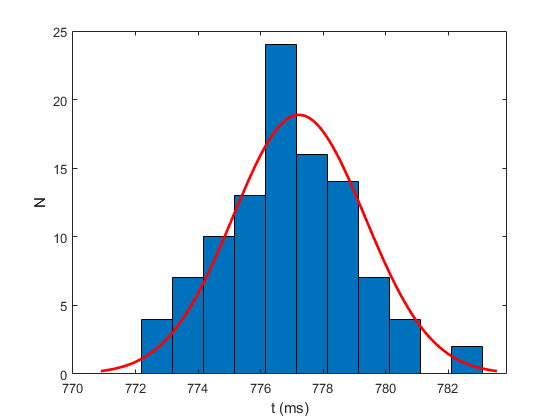

% histogram fitted 
chihist=figure;
histfit(test)
xlabel("t (ms)")
ylabel("N")
% export
saveas(chihist,'..\img\chi.png');

% calcolo gc2 con formula più corta (g calculated 2)
% for i = 1:nc
%     gc2(i) = (2.*pi./tm(i)).^2  .*  ((l.^2)/(12.*d(i)) + d(i));
% end


% per ogni configurazione calcolo la media del periodo e la sua deviazione
% standard


sigma_t = zeros(nc,1);

for i = 1:nc
    tm(i) = mean(table2array(df2(df2.configuration == uc(i),"period_s")));
    sigma_t(i) = std(table2array(df2(df2.configuration == uc(i),"period_s")));
end

o4 = table(uc,tm,sigma_t,'VariableNames',{'configuration','mean_period','sigma_t'})

o4 = 13×3 table
    configuration    mean_period     sigma_t 
    _____________    ___________    _________

          1            1.9952       0.0037758
          2             1.744        0.019315
          3            1.6457        0.022443
          4            1.6192        0.019199
          5             1.562        0.015779
          6            1.5545       0.0042226
          7            1.5318        0.020136
          8            1.5715        0.020486
          9             1.544        0.018343
         10            1.5858        0.015413
         11            1.5962       0.0038142
         12            1.6035        0.015586
         13            1.6355       0.0087585



% rounding
% o4.mean_period = round(o4.mean_period,2);
% o4.sigma_t = round(o4.sigma_t,2);

% join o4 with df1 in order to obtain distance
o4 = join(o4,df1,"Keys","configuration");
o4.distance_m = (o4.distance_cm-50)/100;

% filter out distance_cm
o4 = o4(:,["configuration","mean_period","sigma_t","distance_m"]);

% compute teoretical period
o4.teo_period = teot(1,o4.distance_m);

tt=(2.*pi./sqrt(g)).*sqrt(((l.^2)./(12.*r))+r); % theoretical curve

% preview
o4

o4 = 13×5 table
    configuration    mean_period     sigma_t     distance_m    teo_period
    _____________    ___________    _________    __________    __________

          1            1.9952       0.0037758        0.1          1.938  
          2             1.744        0.019315       0.15          1.685  
          3            1.6457        0.022443        0.2         1.5753  
          4            1.6192        0.019199       0.22         1.5523  
          5             1.562        0.015779       0.25         1.5322  
          6            1.5545       0.0042226       0.27          1.526  
          7            1.5318        0.020136        0.3         1.5248  
          8            1.5715        0.020486       0.32         1.5283  
          9             1.544        0.018343       0.35         1.5384  


% rounding before exporting


% exporting
writetable(o4,'..\data\output-data-2.csv','Delimiter',',','Encoding','UTF-8')

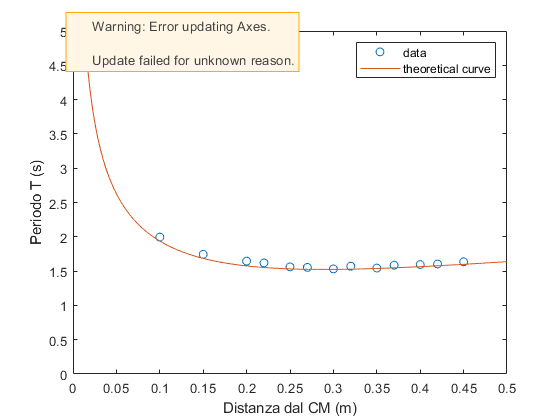


% plotting
plt1=figure;
plot(o4.distance_m,o4.mean_period,'o')
xlabel('Distanza dal CM (m)')
ylabel('Periodo T (s)')
xlim([0,0.5])
ylim([0 5])
hold on
plot(r,tt)
hold off
legend('data','theoretical curve')
saveas(plt1,'..\img\plot1.png');

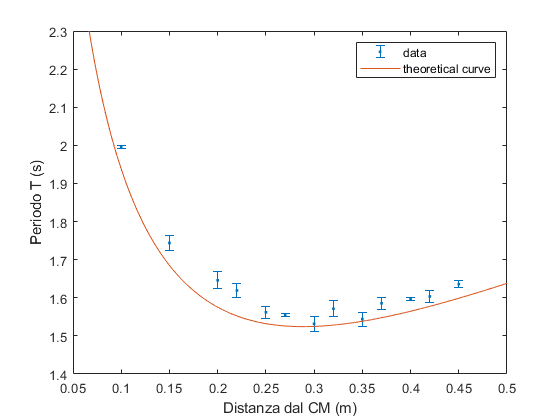


plt2=figure;
errorbar(o4.distance_m,o4.mean_period,o4.sigma_t,o4.sigma_t,'.')
xlabel('Distanza dal CM (m)')
ylabel('Periodo T (s)')
xlim([0,0.5])
hold on
plot(r,tt)
hold off
ylim([1.4 2.3])
xlim([0.05 0.5])
legend('data','theoretical curve')
saveas(plt2,'..\img\plot2.png');

% calcolare chi quadro su questo grafico
% compute chi square
% chio4 = sum(((o4.mean_period-o4.teo_period)./o4.sigma_t).^2)
% chi ridotto
% chio4./(height(o4)-1)

## Metodo dei minimi quadrati

d = o4.distance_m;
y = tm;
x = sqrt(  (repelem(l,length(d))'.^2)./(12.*d) + d   );

% scatterplot
% plot y and x
% plot(x,y,'o')
% xlabel("x")
% ylabel("y")
% determino parametri per applicare metodo minimi quadrati

% numero di punti
n = length(tm);

delta = n.*sum(x.^2) - (sum(x)).^2;

% intercetta
a = (   (sum(x.^2).*sum(y))  - (sum(x).*sum(x.*y))   )./delta

a = -0.0850

% coefficiente angolare
b = (   (n.*sum(x.*y)) - (sum(x).*sum(y))   )./delta

b = 2.1617

% sigma y eq 8.15 Taylor
sigma_y = sqrt(sum((y - repelem(a,n,1) - repelem(b,n,1).*x).^2)./(n - 2)) %sigma_y = round(sigma_y,2)

sigma_y = 0.0194

% errore su a eq. 8.16 Taylor
sigma_a = sigma_y .* sqrt((sum(x.^2))./(delta))

sigma_a = 0.0794

% errore su b eq. 8.17 Taylor
sigma_b = sigma_y .* sqrt(n./delta)

sigma_b = 0.0998

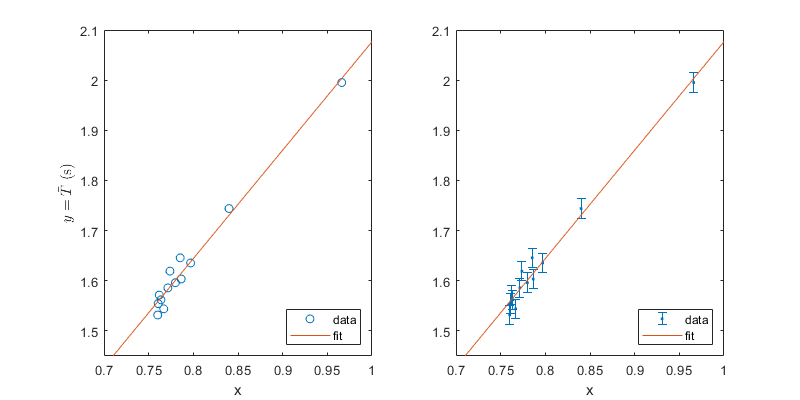

% plotting
plt4=figure;
subplot(1,2,1)
plot(x,y,'o')
hold on
plot(0:1,a+b.*(0:1)')
hold off
legend("data","fit",'Location','southeast')
xlim([0.7 1])
ylim([1.45 2.1])
xlabel("x")
ylabel("$y = \bar{T}$ (s)","Interpreter","latex")
subplot(1,2,2)
errorbar(x,y,repelem(sigma_y,length(y),1),repelem(sigma_y,length(y),1),'.')
hold on
plot(0:1,a+b.*(0:1)')
xlabel("x")
hold off
legend("data","fit",'Location','southeast')
xlim([0.7 1])
ylim([1.45 2.1])
plt4.Position = [10 10 800 400];
saveas(plt4,'..\img\plot4.png');

% stimo g dal coefficiente angolare
% gmq sta per "g minimi quadrati"

% approssimo b in base alle cifre significative dei loro errori
% sigma_b = round(sigma_b,2)
% b = round(b,1)
gmq = (2.*pi./b).^2

gmq = 8.4482

gmq_max = (2.*pi./(b-sigma_b)).^2

gmq_max = 9.2861

gmq_min = (2.*pi./(b+sigma_b)).^2

gmq_min = 7.7189

gmq_max - gmq

ans = 0.8378

gmq - gmq_min

ans = 0.7294

% propagazione erorre su gmq
sigma_g = 8.*pi.^2.*sigma_b./b.^3

sigma_g = 0.7803

sigma_g = round(sigma_g,1)

sigma_g = 0.8000

gmq = round(gmq,1)

gmq = 8.4000

t = abs(9.8-gmq)/sigma_g

t = 1.7500

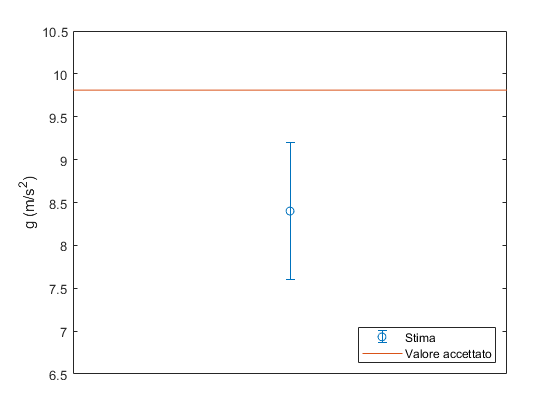

gplot1=figure;
errorbar(1,gmq,sigma_g,sigma_g,'o')
hold on
plot(0:2,repelem(9.81,3,1))
hold off
ylim([6.5 10.5])
set(gca,'XTick',[])
legend("Stima","Valore accettato","Location","southeast")
ylabel("g (m/s^2)")
% export
saveas(gplot1,'..\img\gplot1.png');

il risultato ottenuto dal metodo dei minimi quadrati è $g = 8.4 \pm 0.8 \; m/s^2$ e dista 1.8 $\sigma$ dal valore accettato di $9.8 \; m/s^2$ (lo scarto normalizzato)

% si può associare un errore a gmq, lo faccio dopo ma forse nono è
% importante

% add coefficiente di correlazione linear
rl = sum((x - repelem(mean(x),length(x),1))  .*  (y - repelem(mean(y),length(y),1))) ./ (  sqrt(sum((x - repelem(mean(x),length(x),1)).^2) .* sum((y - repelem(mean(y),length(y),1)).^2))  );
rl = round(rl,2)

rl = 0.9900

Dal coefficiente di combinazione lineare $r = 0.99$ è possibile comprendere come le grandezze x e y risultino linearmente correlate e dunque si adattano bene alla retta di 

## Determino g (media)

% join df1 e df2
df2 = join(df2,df1,"Keys","configuration");
df2.distance_cm = df2.distance_cm - 50;
df2.distance_m = df2.distance_cm/100;
df2 = df2(:,["configuration","event","period_s","distance_m"]);

% calculate g
for i = 1:height(df2)
    df2.g_calc(i) = (2.*pi./df2.period_s(i)).^2  .*  ((l.^2)/(12.*df2.distance_m(i)) + df2.distance_m(i));
end

% preview 
df2

df2 = 1118×5 table
    configuration    event    period_s    distance_m    g_calc
    _____________    _____    ________    __________    ______

          1            1       2.004         0.1        9.1749
          1            2        1.99         0.1        9.3044
          1            3       1.996         0.1        9.2486
          1            4           2         0.1        9.2116
          1            5       1.992         0.1        9.2858
          1            6       1.996         0.1        9.2486
          1            7       1.994         0.1        9.2672
          1            8       1.994         0.1        9.2672
          1            9       1.992         0.1        9.2858
          1           10           2         0.1        9.2116
          1           11        1.99         0.1      


% calculate mean and standard deviation of g
for i = 1:nc
    g_calc_mean(i) = mean(table2array(df2(df2.configuration == uc(i),"g_calc")));
    g_sigma(i) = std(table2array(df2(df2.configuration == uc(i),"g_calc")));
end

o5 = table(uc,g_calc_mean',g_sigma','VariableNames',{'configuration','g','sigma'})

o5 = 13×3 table
    configuration      g        sigma  
    _____________    ______    ________

          1          9.2563    0.035038
          2          9.1608     0.20454
          3          8.9934      0.2373
          4          9.0201     0.21584
          5          9.4413     0.18639
          6          9.4542     0.05133
          7          9.7266     0.25429
          8          9.2835     0.24095
          9          9.7428     0.23549
         10          9.3464     0.18536
         11           9.426    0.045028
         12          9.4976     0.18092
         13           9.375    0.098173


% rounding
o5.g = round(o5.g,2);
o5.sigma = round(o5.sigma,2);

% preview
o5

o5 = 13×3 table
    configuration     g      sigma
    _____________    ____    _____

          1          9.26    0.04 
          2          9.16     0.2 
          3          8.99    0.24 
          4          9.02    0.22 
          5          9.44    0.19 
          6          9.45    0.05 
          7          9.73    0.25 
          8          9.28    0.24 
          9          9.74    0.24 
         10          9.35    0.19 
         11          9.43    0.05 
         12           9.5    0.18 
         13          9.38     0.1 


% chi quadro
cg = sum(((o5.g-repelem(9.81,height(o5))')./o5.sigma).^2)

cg = 369.9672

% mean g
round(mean(o5.g),1)

ans = 9.4000

mean(o5.sigma)

ans = 0.1685

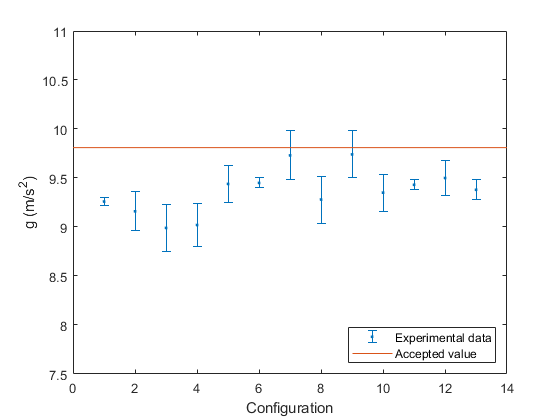

% plotting
plt5=figure;
errorbar(o5.configuration,o5.g,o5.sigma,'.')
hold on
plot(0:length(o5.configuration)+1,repelem(9.81,length(0:length(o5.configuration))+1,1))
hold off
xlim([0 height(o5)+1])
ylim([7.5 11])
legend("Experimental data","Accepted value","Location","southeast")
xlabel("Configuration")
ylabel("g (m/s^2)")
% export
saveas(plt5,'..\img\plot5.png');

## Exporting

% converting array to string
% d=string(d);
% tm=string(tm);
% gc=string(gc);
% regc=string(regc);
% 
% for i=1:nc
%     d(i)=sprintf('%.3f',d(i));
%     tm(i)=sprintf('%.2f',tm(i));
%     gc(i)=sprintf('%.1f',gc(i));
%     regc(i)=sprintf('%.2f',regc(i));
% end

% generating output 1
% output1=array2table(cat(2,string(uc),d,gc,dgc,regc,uomg),"VariableNames",{'configuration','distance_CM','gravitational_acceleration','uncertainty','relative_error','uom'});
% output1=sortrows(output1,"distance_CM");
% output1=output1(:,{'configuration','gravitational_acceleration','uncertainty','relative_error','uom'}) %remove distance_CM

% generating output2
% output2=sortrows(array2table(cat(2,string(uc),d,dd,uomd,tm,dtm,uomt),"VariableNames",{'configuration','distance_CM','uncertainty_distance','uom_distance','time','uncertainty_time','uom_time'}),"distance_CM")
% generating output3
% output3=array2table(cat(2,gm,dgm,uomg(1),regm),"VariableNames",{'gravitational_acceleration','uncertainty','uom','relative_error'})

% exporting csv
% writetable(output1,'..\data\output-data-1.csv','Delimiter',',','Encoding','UTF-8')
% writetable(output2,'..\data\output-data-2.csv','Delimiter',',','Encoding','UTF-8')
% writetable(output3,'..\data\output-data-3.csv','Delimiter',',','Encoding','UTF-8')

% exporting mlx2m
mlxloc = fullfile(pwd,'livescript.mlx');
fileout = 'script.m';
matlab.internal.liveeditor.openAndConvert(mlxloc,fileout);

## Functions

function chi = chi(x,y,sigma) 
    % x valore atteso
    % y valore osservato
    % sigma deviazione
    for i = 1:length(x)
        c(i) = ((y(i)-x(i))./sigma(i)).^2;
    end
    chi = sum(c);
end

function tt = teot(l,r)
    % l lunghezza pendolo
    % r distanza asse di rotazione - centro di massa
    tt=(2.*pi./sqrt(9.81)).*sqrt(((l.^2)./(12.*r))+r);
end